% Working With Tables 

## Excersice 1.1

% create a row vector uno , column vector vn and 2 by 3 matrix

uno = [1,2,3];
vn =[1;2;3];
mn = [1,2,3;4,5,6];

% create eveenly spaced vector named nd [1,15]
nd =[1:2:15]

nd =      1     3     5     7     9    11    13    15


% create  1 by 2 row vector with the first name Jhone and Doe
ot = ["Jhone","Doe"]

ot = 1×2 string array
    "Jhone"    "Doe"


% create a random matrix 3 by 2
A= rand(3,2);

% extraction element at 3,2
A(3,2)

ans = 0.0975

% extraction of row 3

A(3,:)

ans =     0.1270    0.0975


% extraction of column 2
A(:,2)

ans =     0.9134
    0.6324
    0.0975


% extraction element row 2  and 3 with column 1 and 2

A(2:3,1:2)

ans =     0.9058    0.6324
    0.1270    0.0975


% extraction of row 1 and 3

A([1 3],:)

ans =     0.8147    0.9134
    0.1270    0.0975


% extraction of element in the last row, column 2
A(end,2)

ans = 0.0975

% Reversing the order
% Reversing the order of the rows in matrix A
 A(end:-1:1, 2)

ans =     0.0975
    0.6324
    0.9134


rng(22)


a=rand(3,2);
ab=[11,22,33]';


cm = {1,2,3 ; "Bunogiorno a tutti",a,ab }

cm = 2×3 cell array
    {[                   1]}    {[       2]}    {[       3]}
    {["Bunogiorno a tutti"]}    {3×2 double}    {3×1 double}


% structure
st = struct;
st.a = 1;
st.b=2;
st.c= 3;
st.d ="Bunogiorno a tutti";
st.e = rand(3,2);
st.f = [11,22,33]';

% extract the third elemtn from st
st.c

ans = 3

## Tables

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 10);

% Specify sheet and range
opts.Sheet = "data";
opts.DataRange = "A2:J108";

% Specify column names and types
opts.VariableNames = ["Code", "Surname", "Name", "Gender", "BirthDate", "Education", "Wage", "CommutingTime", "SmartWorkHours", "Seniority"];
opts.VariableTypes = ["string", "string", "string", "categorical", "datetime", "categorical", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["Code", "Surname", "Name"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Code", "Surname", "Name", "Gender", "Education"], "EmptyFieldRule", "auto");

% Import the data
Firm2 = readtable("D:\2018\Github_Push\Data_Science\Data_Science_With_matlab\Firm.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
Firm2

Firm2 = 107×10 table
     Code        Surname           Name          Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _______    ___________    _______________    ______    ___________    _________    ____    _____________    ______________    _________

    "P0211"    "BASILICO"     "TIZIANA"            F       16-Jun-1991        A        1877         27                10             11    
    "P0212"    "BONINO"       "PAOLO"              M       01-Jul-1993        B        2375         35                12              8    
    "P0213"    "GRI"          "ALBERTO"            M       19-Oct-1987        

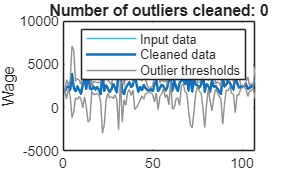

% Fill outliers
[newTable,outlierIndices,lo,hi] = filloutliers(Firm2,"linear","movmedian",2, ...
    DataVariables="Wage");

% Display results
figure
plot(Firm2.Wage,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable.Wage,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")

% Plot outliers
plot(find(outlierIndices(:,7)),Firm2.Wage(outlierIndices(:,7)),"x", ...
    Color=[145 145 145]/255,DisplayName="Outliers")

% Plot filled outliers
plot(find(outlierIndices(:,7)),newTable.Wage(outlierIndices(:,7)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled outliers")

% Plot outlier thresholds
plot([(1:numel(Firm2.Wage))'; missing; (1:numel(Firm2.Wage))'], ...
    [hi.Wage(:); missing; lo.Wage(:)],Color=[145 145 145]/255, ...
    DisplayName="Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,7)))
legend
ylabel("Wage")

clear lo hi

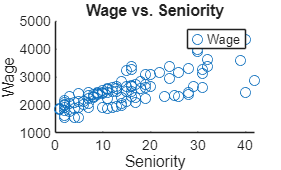

% Create scatter of Firm2.Seniority and Firm2.Wage
s = scatter(Firm2,"Seniority","Wage","DisplayName","Wage");

% Add xlabel, ylabel, title, and legend
xlabel("Seniority")
ylabel("Wage")
title("Wage vs. Seniority")
legend

Table0 = readtable("Firm.xlsx",ReadRowNames=false)

Table0 = 107×10 table
      Code          Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
    _________    _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    {'P0211'}    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    {'P0212'}    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    {'P0213'}    {'GRI'      }    {'ALBERTO'      }  


% extract the first 5 values of wage from the dataset
firstfive = Table0.Wage(1:5,:)

firstfive =         1877
        2375
        2450
        2037
        3893


% or
Table0{1:5,"Wage"}

ans =         1877
        2375
        2450
        2037
        3893


% extract the first five values of both wage and seniority

val1 = Table0{1:5,["Seniority" "Wage"]};
% or

Table0(1:5, ["Wage" "Seniority"])

ans = 5×2 table
    Wage    Seniority
    ____    _________

    1877       11    
    2375        8    
    2450       11    
    2037        7    
    3893       30    


% or

[Table0.Wage(1:5),Table0.Seniority(1:5)]

ans =         1877          11
        2375           8
        2450          11
        2037           7
        3893          30


Table1= readtable("Firm.xlsx", ReadRowNames=true)

Table1 = 107×9 table
                Surname             Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    _________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO' }    {'TIZIANA'      }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0212    {'BONINO'   }    {'PAOLO'        }    {'M'}     01-Jul-1993      {'B'}      2375         35                12              8    
    P0213    {'GRI'      }    {'ALBERTO'      }    {'

% extract subject P0219
Table1("P0219",:)

ans = 1×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    __________    ______    ___________    _________    ____    _____________    ______________    _________

    P0219    {'DE SCALZI'}    {'DAVIDE'}    {'M'}     03-Oct-1999      {'B'}      2016         19                4               2    


% extract subject P0219  and P0476
Table1([ "P0219" "P0476"],:)

ans = 2×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    __________    ______    ___________    _________    ____    _____________    ______________    _________

    P0219    {'DE SCALZI'}    {'DAVIDE'}    {'M'}     03-Oct-1999      {'B'}      2016         19                 4              2    
    P0476    {'FAVELLA'  }    {'FELICE'}    {'M'}     25-Sep-1991      {'C'}      2338         21                12              7    



% or
Table1({'P0219' 'P0476'},:)

ans = 2×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             _____________    __________    ______    ___________    _________    ____    _____________    ______________    _________

    P0219    {'DE SCALZI'}    {'DAVIDE'}    {'M'}     03-Oct-1999      {'B'}      2016         19                 4              2    
    P0476    {'FAVELLA'  }    {'FELICE'}    {'M'}     25-Sep-1991      {'C'}      2338         21                12              7    


% EXTRACT only female students 

BOO1 = Table1.Gender=="F";

Table1(BOO1,:)

ans = 46×9 table
                Surname               Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ______________    __________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO'  }    {'TIZIANA'       }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0214    {'BARBIERI'  }    {'ROSSANA'       }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0215    {'PRENNA'    }    {'FEDERICA'      }

% OR
Table1(Table1.Gender=="F",:)

ans = 46×9 table
                Surname               Name           Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ______________    __________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0211    {'BASILICO'  }    {'TIZIANA'       }    {'F'}     16-Jun-1991      {'A'}      1877         27                10             11    
    P0214    {'BARBIERI'  }    {'ROSSANA'       }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0215    {'PRENNA'    }    {'FEDERICA'      }

% EXTRACT All female student with educational level is B
Table1(Table1.Gender=="F" & Table1.Education=="B",:)

ans = 15×9 table
                 Surname                  Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ________________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0214    {'BARBIERI'    }    {'ROSSANA'            }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0220    {'BARBIERI'    }    {'LAURA'              }    {'F'}     10-Mar-1999      {'B'}      1635         45                16              2    
    P0225    {'SOFFIE

con1=Table1(Table1.Gender=="F" & Table1.Education=="B",:);
con2=Table1(Table1.Gender=="M" & Table1.Wage>4000,:);

% extract female with education level b or male with >4000 salary

Table1((Table1.Gender=="F" & Table1.Education=="B") |(Table1.Gender=="M" & Table1.Wage>4000),:)

ans = 20×9 table
                 Surname                  Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ________________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0214    {'BARBIERI'    }    {'ROSSANA'            }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0220    {'BARBIERI'    }    {'LAURA'              }    {'F'}     10-Mar-1999      {'B'}      1635         45                16              2    
    P0224    {'VELARD

% extract those whose salary >3000 and less than 3500
anss=Table1(Table1.Wage>=3000 & Table1.Wage<=3500,:);

% EXTRACT SURNAME start with "CAS"

Table1(startsWith (Table1.Surname,"CAS"),:)

ans = 4×9 table
                Surname          Name       Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ______________    _________    ______    ___________    _________    ____    _____________    ______________    _________

    P0287    {'CASETTA'   }    {'CATIA'}    {'F'}     21-Nov-1973      {'B'}      2629         24                6              19    
    P0472    {'CASTELLANO'}    {'PAOLA'}    {'F'}     02-Mar-1993      {'C'}      2407         33                8               5    
    P0508    {'CASELLA'   }    {'LAURA'}    {'F'}     28-Jul-1983      {'C'}      2675


% Extract name endswith "LA"

Table1(endsWith(Table1.Name,"LA"),:)

ans = 11×9 table
                 Surname                  Name              Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ________________    _______________________    ______    ___________    _________    ____    _____________    ______________    _________

    P0225    {'SOFFIETTI'   }    {'MARINA ANGELA'      }    {'F'}     12-Jun-1975      {'B'}      2226         47                14             11    
    P0246    {'ORLANDI'     }    {'ALBERTO LUCA NICOLA'}    {'M'}     24-Jun-1999      {'B'}      1812         28                10              2    
    P0249    {'FERRER

% display person whose name start with R and endwith O

Table1((startsWith(Table1.Name,"R") & endsWith(Table1.Name,"O")),:)

ans = 4×9 table
                   Surname              Name        Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ___________________    ____________    ______    ___________    _________    ____    _____________    ______________    _________

    P0233    {'ROSSI'          }    {'RICCARDO'}    {'M'}     14-May-1991      {'A'}      1931         17                 4             13    
    P0254    {'NOVELLO'        }    {'ROBERTO' }    {'M'}     17-Nov-1998      {'A'}      1559         37                14              2    
    P0411    {'MOURGLIA LESLEY'}    {'ROBERTO' }    {'

% EXtract person whose name start with R and end with O or A

Table1(startsWith(Table1.Name,"R") & endsWith(Table1.Name,"O" |"A"),:)

ans = 8×9 table
                   Surname              Name        Gender     BirthDate     Education    Wage    CommutingTime    SmartWorkHours    Seniority
             ___________________    ____________    ______    ___________    _________    ____    _____________    ______________    _________

    P0214    {'BARBIERI'       }    {'ROSSANA' }    {'F'}     28-Jan-1992      {'B'}      2037         16                 6              7    
    P0231    {'GRILLO'         }    {'ROBERTA' }    {'F'}     30-Jun-1997      {'A'}      1562         17                 4              5    
    P0233    {'ROSSI'          }    {'RICCARDO'}    {'


% EXtract person whose name start with R and end with O or A and atmost 7
% character
Table1(startsWith(Table1.Name,"R") & endsWith(Table1.Name,"O" | "A") & strlength(Table1.Name) <= 7, :)

% load citiesitaly.mat
load citiesItaly.mat

% Create a new table CIT whose row and columns are in reverse order compare
% to citiesItaly

CIT = citiesItaly(end:-1:1,end:-1:1)

CIT = 103×7 table
                billsoverd    bankrup    export    unemploy    pensions    depos     addedval
                __________    _______    ______    ________    ________    ______    ________

    Oristano      34.26         18.3       2.7      21.44       8733.8     5310.8      12336 
    Cagliari      43.56        34.64     19.13      23.98        10662     6669.9      14782 
    Nuoro         31.91        12.19      1.82      15.38       8607.8     5509.6      11850 
    Sassari       34.03         36.2         5      17.82         9676     5762.6      15104 
    Siracusa      41.53        55.68     58.34      18.33       9575.3     4408.6      12443 


citiesItaly.Properties.Description

ans =     'The citiesItaly dataset contains 107 records for the 107 provinces of Italy for seven indicators concerning the quality of life: The 7 variables are:
     addedval = added value per capita
     depost = amount of bank deposits per inhabitant
     unemploy = unemployment rate
     export = percentage of export divided by GNP of the province
     bankrup = percentage of bankruptcy declarations on active companies
     billsover = bills overdue indicator (percentage of bills protested on bills issued)
     The data come from the Italian financial newspaper Il Sole 24 Ore, which every year produces the quality of life ranking of the Italian provinces.'


% computer CIT2 = citiesitalies + CIT
CIT2 = citiesItaly+ CIT;

% display the first 3rd , 3rd end from last and last row from all 3 table

CIT2([1 3 end-3 end],:)

ans = 4×7 table
                addedval    depos    pensions    unemploy    export    bankrup    billsoverd
                ________    _____    ________    ________    ______    _______    __________

    Torino       47167      19925     23901       15.72      64.44      59.06       74.96   
    Novara       44254      19541     23477       10.76      84.84      55.42       67.66   
    Sassari      30207      11525     19352       35.64         10       72.4       68.06   
    Oristano     24673      10622     17468       42.88        5.4       36.6       68.52   


CIT([1 3 end-3 end],:)

ans = 4×7 table
                billsoverd    bankrup    export    unemploy    pensions    depos     addedval
                __________    _______    ______    ________    ________    ______    ________

    Oristano      34.26         18.3       2.7      21.44       8733.8     5310.8     12336  
    Nuoro         31.91        12.19      1.82      15.38       8607.8     5509.6     11850  
    Cuneo          17.3        12.33     36.75       3.58       9611.1     9706.7     20479  
    Torino        37.48        29.53     32.22       7.86        11950     9962.6     23583  


citiesItaly([1 3 end-3 end],:)

ans = 4×7 table
                addedval    depos     pensions    unemploy    export    bankrup    billsoverd
                ________    ______    ________    ________    ______    _______    __________

    Torino       23583      9962.6      11950       7.86      32.22      29.53       37.48   
    Novara       22127      9770.6      11739       5.38      42.42      27.71       33.83   
    Sassari      15104      5762.6       9676      17.82          5       36.2       34.03   
    Oristano     12336      5310.8     8733.8      21.44        2.7       18.3       34.26   


## Basic Programming